%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

f_0 = f_a - axion_linewidth;
Q_resonator_original = 1e5

Q_resonator_original = 100000

Q_resonator = Q_resonator_original / heterodyning_ratio;
band_width = f_0 / Q_resonator

band_width = 4.8355e+03

band = [f_0-band_width/2, f_0+band_width/2];
limiting_band = [f_0-5*axion_linewidth, f_0+5*axion_linewidth];

%% finish generation
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_resonator_original);

INPUT_DATA = signal + noise;

tau_iwave = 2e-4;
f_guess = f_0;

R = @(f_ax, f_res) 1 ./ (1 + 4*Q_resonator_original^2 * (f_ax - f_res).^2 ./ f_res.^2 );

STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
state_res = resonator_setup();
f_iwave = zeros(1, length(INPUT_DATA));
xs = zeros(1, length(INPUT_DATA));
f_current = f_0

f_current = 2.4177e+07

for i = 1 : length(INPUT_DATA)
    x = INPUT_DATA(i);
    x = x * R(f_axion(i), f_current);
    [state_res, y] = resonator_step(state_res, x, f_current, Q_resonator, f_sampling);
    [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, y);
    f_current = pfout;
    if f_current > limiting_band(2)
        f_current = limiting_band(2);
    elseif f_current < limiting_band(1)
        f_current = limiting_band(1);
    end
    f_iwave(i) = f_current;
    xs(i) = x; %this is for 'do we know if iwave is locked'
end

% front to chop off
start_secs = 0.0005;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);

start_small = round(start / div)

start_small = 125

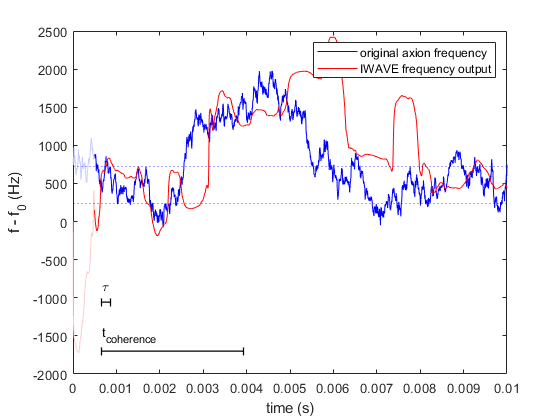

figure
%adstyle(8, 8);

plot(t_small(start_small:end), f_axion_small(start_small:end)-f_0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start_small),   f_axion_small(1:start_small)  -f_0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start_small:end), f_iwave_small(start_small:end)-f_0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start_small),   f_iwave_small(1:start_small)  -f_0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
%ylim(y_lim)
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_lim = ylim();
x_lim = xlim();
y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);
x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;
plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

%plot(t_small, f_iwave_small - band_width/2 -f_0, ':r', 'HandleVisibility','off')
%plot(t_small, f_iwave_small + band_width/2 -f_0, ':r', 'HandleVisibility','off')
yline([f_a-axion_linewidth/2 - f_0, f_a + axion_linewidth/2 - f_0], ':b', 'HandleVisibility','off')

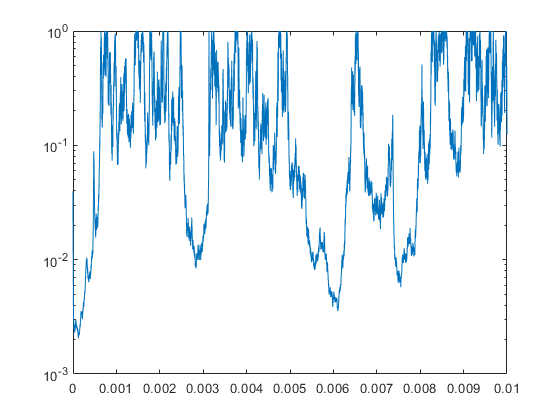

figure
R_ = R(f_axion, f_iwave);
%R_small = R_(slice);
plot(t, R_);
set(gca, 'yscale', 'log')

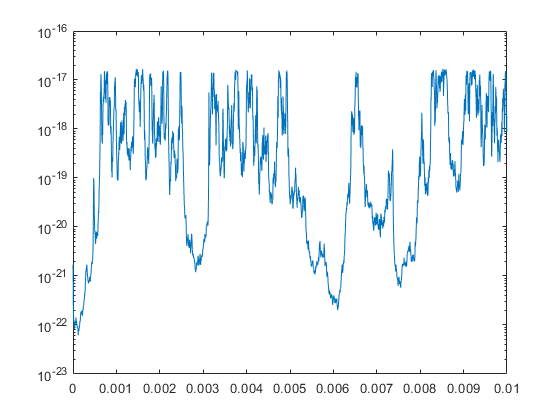

powers = zeros(1, floor(length(INPUT_DATA)/1000));
j = 0;
for i = 1 : 1000 : length(INPUT_DATA) - 1000
    j = j+1;
    powers(j) = bandpower(xs(i:i+1000));
end

figure
plot(t_small(1:end-1), powers)
set(gca, 'yscale','log')

rms(f_axion(start:end) - f_iwave(start:end))

ans = 632.1409

rms(f_axion(start:end) - f_0)

ans = 915.8061

%rms(f_axion(start:(end+1)/2) - f_iwave(start:(end+1)/2))
%rms(f_axion(start:(end+1)/2) - f_0)